## Analisi del sistema a ciclo chiuso

Nel seguente script verranno analizzate le performance del controllore applicato al sistema fornito.

### Sistema in Esame


$$\begin{cases}
\dot x_1 =x_2 \\
\dot{x_2} = -\frac{g}{l} sin x_1- \frac{b}{ml^2}x_2+ \frac{u(t)}{ml^2}\\
y=x_1
\end{cases}$$


In questa analisi, a differenza dell'analisi effettuata a ciclo aperto, abbiamo la presenza del controllore. Lo scopo del seguente codice è quello di mostrare quelli che sono le consegueze dell'uso di un controllore sul nostro sistema in esame. L'analisi è partita considerando valori di controllori costanti e si è analizzato come diventasse il piano delle fasi con il sistema in esame,

Dalla figura a destra possiamo notare come il piano delle fasi venga modificato dall'azione del controllore, in quanto controllori diversi portano ad avere piani delle fasi diversi. Nello specifico si nota che con l'aumentare dell'influenza del controllore il piano dele fasi si modifica portando il sistema ad assestarsi intorno a nuovi punti di equilibrio. 

% Script illustrativo per la simulazione di sistemi dinamici nonlineari

mkdir('Immagini_Ciclo_Chiuso');

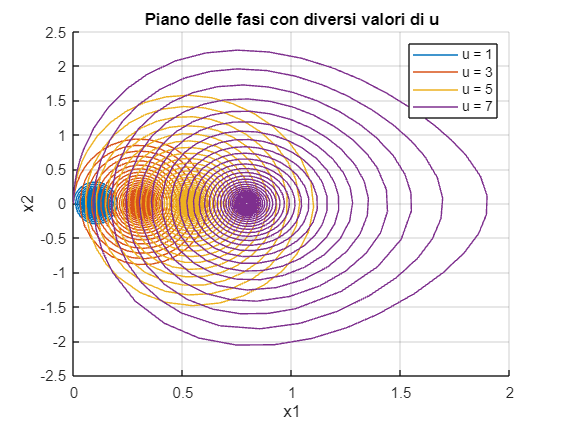

tspan = [0 100];  % intervallo di simulazione
x_1_0 = 0; 
x_2_0 = 0; % condizioni iniziali
x0 = [x_1_0 x_2_0];
r=pi;
u_e=0;
r_nl=pi;
K = [18235, 53.9];
Kr = 18235;
% Plot del piano delle fasi
figure;  % Crea una nuova figura per il plot
hold on; % Mantiene il plot attuale per aggiungere nuovi plot

for u = 1:2:7
    % Simulazione del sistema
    [t, x] = ode45(@(t, x) PWsimulink(t, x, u), tspan, x0);

    % Plot del piano delle fasi
    plot(x(:, 1), x(:, 2), 'DisplayName', ['u = ', num2str(u)]);
      saveas(gcf, 'Immagini_Ciclo_Chiuso/PianoFasi.png');
end
% Decorazioni del grafico
xlabel('x1');
ylabel('x2');
title('Piano delle fasi con diversi valori di u');
legend show;  % Mostra la legenda con i nomi dei plot
grid on;

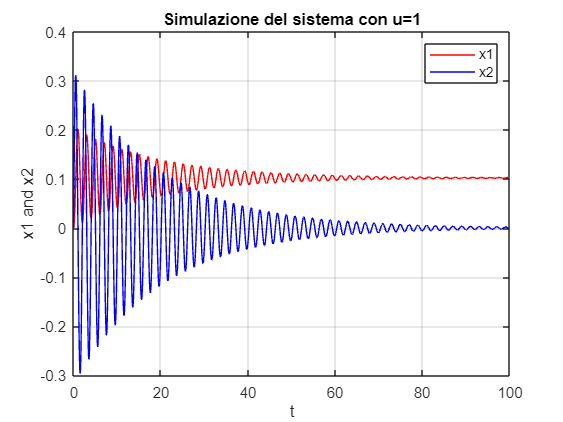

 

% Simulazione del sistema con u = 1
[t, x] = ode45(@(t, x) PWsimulink(t, x, 1), tspan, x0);

% Plot del tempo contro x1 e x2 per u = 1
figure;
plot(t, x(:, 1), 'r', t, x(:, 2), 'b');
grid on;
xlabel('t');
ylabel('x1 and x2');
legend('x1', 'x2');
title('Simulazione del sistema con u=1');
 saveas(gcf, 'Immagini_Ciclo_Chiuso/PianoFasi1.png');

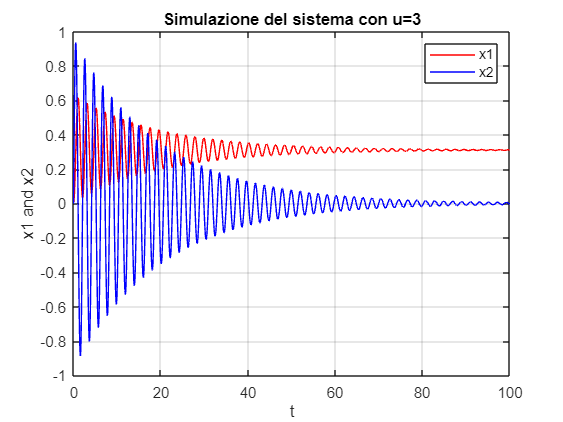

% Simulazione del sistema con u = 3
[t, x] = ode45(@(t, x) PWsimulink(t, x, 3), tspan, x0);

% Plot del tempo contro x1 e x2 per u = 3
figure;
plot(t, x(:, 1), 'r', t, x(:, 2), 'b');
grid on;
xlabel('t');
ylabel('x1 and x2');
legend('x1', 'x2');
title('Simulazione del sistema con u=3');

 saveas(gcf, 'Immagini_Ciclo_Chiuso/PianoFasi2.png');

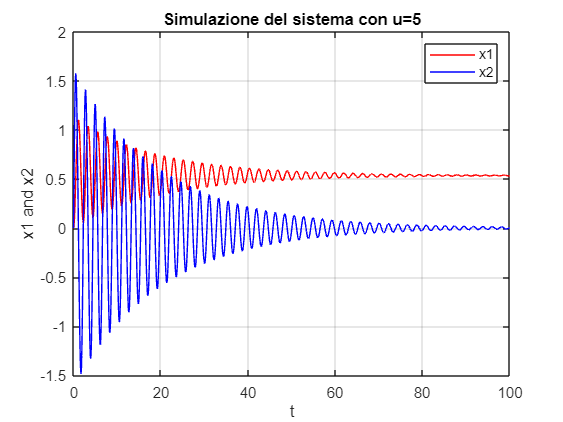

% Simulazione del sistema con u = 5
[t, x] = ode45(@(t, x) PWsimulink(t, x, 5), tspan, x0);

% Plot del tempo contro x1 e x2 per u = 5
figure;
plot(t, x(:, 1), 'r', t, x(:, 2), 'b');
grid on;
xlabel('t');
ylabel('x1 and x2');
legend('x1', 'x2');
title('Simulazione del sistema con u=5');
 saveas(gcf, 'Immagini_Ciclo_Chiuso/PianoFasi3.png');

Il controllore proposto è del tipo: $u=-\textrm{Kx}\left(t\right)+K_r r\left(t\right)$ con $K=\left\lbrack 18235,53\ldotp 9\right\rbrack ;k_r =18235$.

Come possiamo notare dai seguenti due grafici grazie al controllore proposto il pendolo rimane stabile nel suo punto di equilibrio instabile dato che la sua posizione rimane sempre a 3.14 con velocità nulla . Questa cosa viene confermata anche dal piano delle fasi

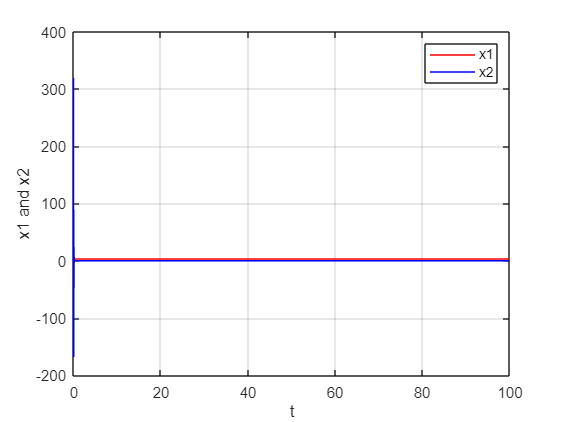

% Simulazione del sistema con u = -K*x+Kr*r(t)
x_1_0 = 3.14; x_2_0 = 0; % condizioni iniziali
x_e = [x_1_0 x_2_0];

% Utilizzeremo il solver 'ode45' (anche altri solver sono disponibili in Matlab)
[t, x] = ode45(@Controller_model, tspan, x0);

% Otteniamo le variabili di stato in due vettori separati
x1 = x(:,1);
x2 = x(:,2);

% Plot dei risultati
plot(t,x1,'r',t,x2,'b'),grid
xlabel('t'),ylabel('x1 and x2')
legend('x1','x2')

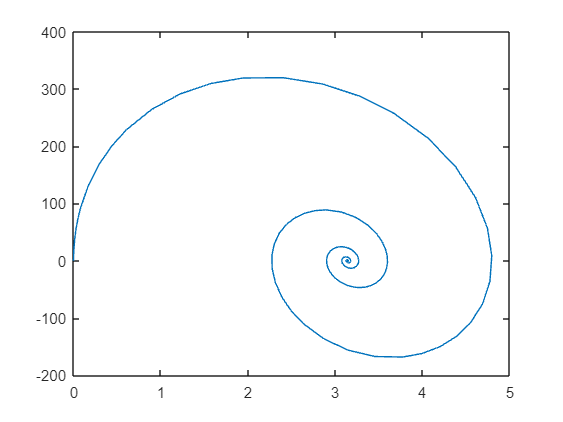


% Plot di una traiettoria del piano delle fasi
% Nota: per un diagramma delle fasi complto bisogna creare un ciclo for...
 figure()
 plot(x1,x2)
 saveas(gcf, 'Immagini_Ciclo_Chiuso/CicloChiuso.png');

#### Simulazione e plot

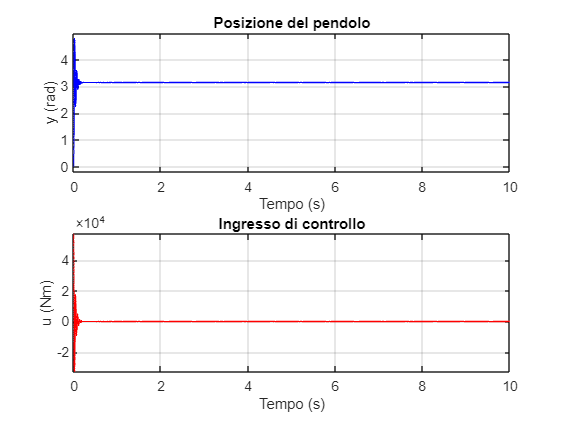

standard_model = 'WP1CicloChiuso.slx';
open_system(standard_model);
data = sim(standard_model, 10);
plot_data(data, "WP1CicloChiuso")
saveas(gcf, 'Immagini_Ciclo_Chiuso/Results.png');

#### Analisi

results=stepinfo(data.y,data.t);
disp('Step Information for the Output');

Step Information for the Output


disp(results);

         RiseTime: 0.0089
    TransientTime: 0.1452
     SettlingTime: 0.1452
      SettlingMin: 2.2690
      SettlingMax: 4.7937
        Overshoot: 52.6662
       Undershoot: 0
             Peak: 4.7937
         PeakTime: 0.0238



function xdot = Controller_model(t, x)
    % Definizioni dei parametri
    m = 1; 
    l = 1;
    b = 0.1;
    g = 9.81;
    K = [18235, 53.9];
    kr = 18235;
    r = pi;
    
    x1 = x(1);
    x2 = x(2);

    % Calcola l'uscita del controllore
    u = -K * [x1; x2] + kr * r;

    % Calcola le derivate delle variabili di stato
    x1_dot = x2;
    x2_dot = (-g/l) * sin(x1) - ((b * x2) / (m * l^2)) + (u / (m * l^2));

    % Assegna i valori di x1_dot e x2_dot a xdot
    xdot = [x1_dot; x2_dot];
  
end

function x_dot = PWsimulink(~, x, u)
    l = 1;
    g = 9.81;
    b = 0.1;
    m = 1;

    x1 = x(1);
    x2 = x(2);

    x1_dot = x2;
    x2_dot = (-g/l) * sin(x1) - (b/(m*l^2)) * x2 + (u/(m*l^2)) ;

    x_dot = [x1_dot; x2_dot];
end
